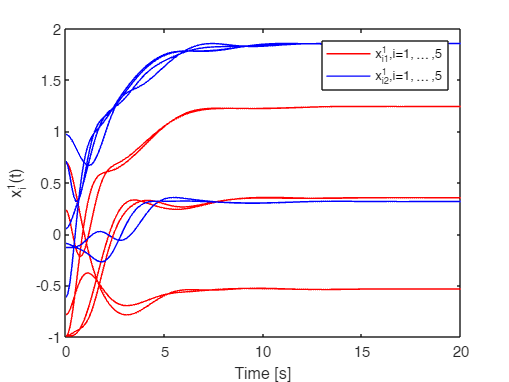

global L d Lsym n
n = 6; m = 6; d = 2; scale = 1;

% G: directed cycle
A1 = [2 0; 0 1];
A3 = [1 0; 0 3];
A5 = [1 0; 0 1];
A2 = [0 0; 0 1];
A4 = [0.75 0.433; 0.433 0.25];
A6 = [0.75 -0.433; -0.433 0.25];

Z = zeros(2,2);
H = [-1 1 0 0 0 0;
     0 -1 1 0 0 0;
     0 0 -1 1 0 0;
     0 0 0 -1 1 0;
     0 0 0 0 -1 1;
     1 0 0 0 0 -1];
W = blkdiag(A1,A2,A3,A4,A5,A6);
L = -W*kron(H,eye(2));
% L = [A1,-A1,Z,Z,Z,Z;
%      Z,A2,-A2,Z,Z,Z;
%      Z,Z,A3,-A3,Z,Z;
%      Z,Z,Z,A4,-A4,Z;
%      Z,Z,Z,Z,A5,-A5;
%      -A6,Z,Z,Z,Z,A6];
Lsym = kron(H,eye(2))'*W*kron(H,eye(2));
% Lsym = [A1+A6,-A1,Z,Z,Z,-A6;
%         -A1,A1+A2,-A2,Z,Z,Z;
%         Z,-A2,A2+A3,-A3,Z,Z;
%         Z,Z,-A3,A3+A4,-A4,Z;
%         Z,Z,Z,-A4,A4+A5,-A5;
%         -A6,Z,Z,Z,-A5,A5+A6];

rng(3);
x0=[];

for i = 1:n
    r = 2*(rand(d,1)-0.5);
    x0 = [x0;r/norm(r)];        
end
x0 = [x0;zeros(d*n,1)];
[t,x] = ode45(@consensus,[0:0.1:20],x0);
x = x';
x1 = x(1:d*n,:); x2 = x(d*n+1:2*d*n,:);
e = zeros(1,length(t));
for i=1:length(t)
    e(1,i) = norm(L*x1(:,i),2);
end
% plotting the states versus time
figure
hold on;
for i=1:n
   plot(t,x1(2*i-1,:),'-r','LineWidth',1);
   plot(t,x1(2*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^1(t)';
box on;
legend({'x_{i1}^1,i=1,\ldots,5','x_{i2}^1,i=1,\ldots,5'},"NumColumns",1)

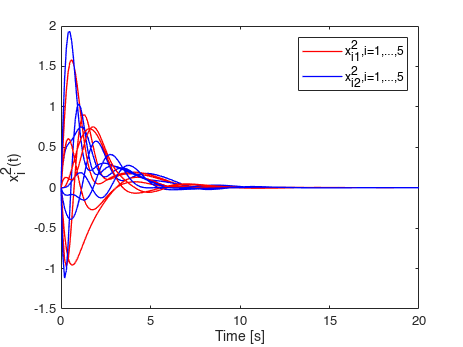


figure
hold on;
for i=1:n
   plot(t,x2(2*i-1,:),'-r','LineWidth',1);
   plot(t,x2(2*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^2(t)';
box on;
legend({'x_{i1}^2,i=1,\ldots,5','x_{i2}^2,i=1,\ldots,5'},"NumColumns",1);

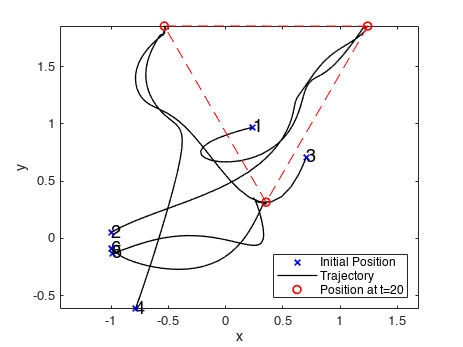



figure
hold on;
for i=1:n
   text(x1(2*i-1,1),x1(2*i,1),num2str(i),"FontSize",14);
   plot(x1(2*i-1,1),x1(2*i,1),'xb','LineWidth',1.25);
   plot(x1(2*i-1,:),x1(2*i,:),'-k','LineWidth',1);
   plot(x1(2*i-1,end),x1(2*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; axis equal;
% ylim([-.8,1.2])
% xlim([-1.5,0.5])
line([x1(1,end),x1(5,end)],[x1(2,end),x1(6,end)],'Color','red','LineStyle','--');
line([x1(1,end),x1(9,end)],[x1(2,end),x1(10,end)],'Color','red','LineStyle','--');
line([x1(9,end),x1(5,end)],[x1(10,end),x1(6,end)],'Color','red','LineStyle','--');
box on
legend({'Initial Position','Trajectory','Position at t=20'},"NumColumns",1,"Location","southeast")

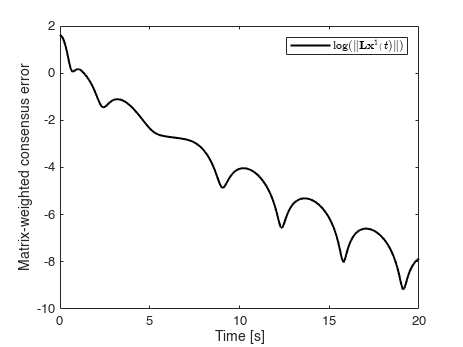



figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}^1(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

function dx = consensus(t,x)
    global L d n Lsym
    ks = 0.5; 
    x1 = x(1:d*n,1);
    x2 = x(d*n+1:2*d*n,1);
    s = x2 + L*x1;
    dx1 = x2;
    dx2 = -2*Lsym*x1 -L*x2 - ks*s;
    dx = [dx1;dx2];
end